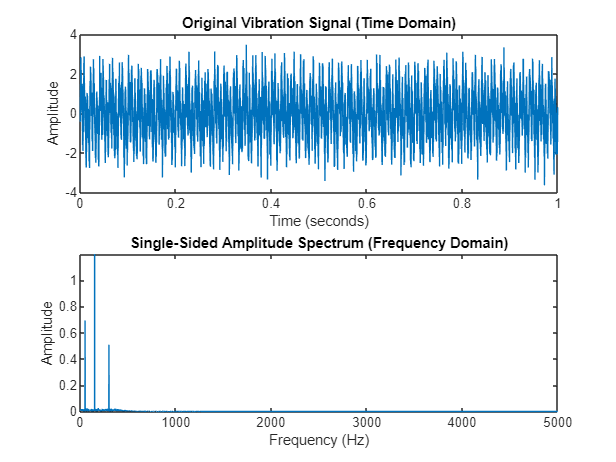

% Step 1: Data Acquisition (Simulated vibration data)
Fs = 10000; % Sampling frequency (Hz)
T = 1/Fs; % Sampling period
L = 10000; % Length of signal
t = (0:L-1)*T; % Time vector
% Simulate a signal (sum of sinusoidal components and some noise)
f1 = 50; % Frequency of first component (e.g., normal vibration)
f2 = 150; % Frequency of second component (e.g., imbalance)
f3 = 300; % Frequency of third component (e.g., misalignment)
signal1 = 0.7*sin(2*pi*f1*t)+1.2*sin(2*pi*f2*t)+0.5*sin(2*pi*f3*t)+0.5*randn(size(t));
% Step 2: Signal Preprocessing - Low-pass filter to remove high-frequency noise
fc = 500; % Cut-off frequency of the low-pass filter
[b,a] = butter(4, fc/(Fs/2), 'low'); % 4th-order Butterworth low-pass filter
filtered_signal=filtfilt(b,a,signal1);
% Apply the filter
% Step 3: Frequency Analysis using FFT
Y = fft(filtered_signal); % Compute the FFT of the filtered signal
P2 = abs(Y/L); % Two-sided spectrum
P1 = P2(1:L/2+1); % Single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1); % Double the amplitude except for DC and Nyquist
% Frequency vector for plotting
f = Fs*(0:(L/2))/L;
% Step 4: Plot the original signal and frequency spectrum
figure;
subplot(2,1,1);
plot(t, signal1);
title('Original Vibration Signal (Time Domain)');
xlabel('Time (seconds)');
ylabel('Amplitude');
subplot(2,1,2);
plot(f, P1);
title('Single-Sided Amplitude Spectrum (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

% Step 5: Anomaly Detection - Identify peaks in the frequency spectrum
threshold = 0.3; % Define a threshold for detecting anomalies
[peaks, locs] = findpeaks(P1, 'MinPeakHeight', threshold);
% Print the detected frequencies
disp('Detected Frequencies (Hz) with potential anomalies:');

Detected Frequencies (Hz) with potential anomalies:


disp(f(locs));

    50   150   300



% Step 6: Root Mean Square (RMS) Calculation
rms_value = rms(filtered_signal);
disp(['RMS Value of the Vibration Signal: ', num2str(rms_value)]);

RMS Value of the Vibration Signal: 1.0553


% Step 7: Health Assessment
safe_rms_threshold = 0.8; % Example threshold for safe operation
if rms_value > safe_rms_threshold
disp('Warning: Excessive vibrations detected. Maintenance required.');
else
    disp('System is operating within safe vibration levels.');
end